### Spatial and Temporal Plots for $\epsilon$

% Spacial variations

L = 1e-2;
N_L = 100;
mu_0 = pi*4e-7;
eps_0 = 8.85418782e-12;
omega = 2*pi*(10^(10));
Z_L = 0.7*1e2;
vp = 0.15e8;
z = linspace(0, L, N_L);

k = omega/vp;

% we use a chebyshev's Low Pass Filter

kc = k*1e2; % cutoff
ks = k*1e3; % sampling freq
rp = 1; % ripple

% Calculate analog cutoff frequency and convert to digital
% wc = 2*pi*kc; % analog cutoff frequency
% wd = 2*pi*kc/ks; % digital cutoff frequency
kd = kc/ks;

% Design Chebyshev Type I filter coefficients
[n, Wn] = cheb1ord(kd, 0.5*kd, rp, 60);
[bc, ac] = cheby1(n, rp, Wn);

% take delta function as input
x = [1, zeros(1, N_L-1)];

Gamma = filter(bc, ac, x); % Gamma(z)
[Hz, w] = freqz(bc, ac, N_L); % freq resp

dGamma = gradient(Gamma); % Gamma'(z)

% find a and b
a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(L/N_L) - trapz(a)*(L/N_L);

% Calculate I(z)
I = exp(-int_a);
D = cumtrapz(I.*b)*(L/N_L) - trapz(I.*b)*(L/N_L);

% find eps(z)
epsz = ( I(N_L)*(Z_L/sqrt(mu_0))*I.^(-1) + I.^(-1).*D ).^(-2);

disp(epsz)

   1.0e-09 *

   0.1422 + 0.1594i   0.1422 + 0.1594i   0.1422 + 0.1594i   0.1422 + 0.1594i   0.1422 + 0.1594i   0.1423 + 0.1594i   0.1423 + 0.1593i   0.1425 + 0.1593i   0.1428 + 0.1592i   0.1433 + 0.1590i   0.1442 + 0.1587i   0.1457 + 0.1582i   0.1479 + 0.1575i   0.1510 + 0.1563i   0.1552 + 0.1546i   0.1607 + 0.1522i   0.1677 + 0.1487i   0.1762 + 0.1440i   0.1861 + 0.1375i   0.1971 + 0.1289i   0.2088 + 0.1180i   0.2206 + 0.1046i   0.2316 + 0.0887i   0.2410 + 0.0710i   0.2483 + 0.0522i   0.2532 + 0.0334i   0.2557 + 0.0157i   0.2565 + 0.0001i   0.2560 - 0.0126i   0.2550 - 0.0221i   0.2541 - 0.0281i   0.2537 - 0.0307i   0.2538 - 0.0301i   0.2544 - 0.0266i   0.2552 - 0.0208i   0.2560 - 0.0131i   0.2564 - 0.0043i   0.2564 + 0.0047i   0.2559 + 0.0134i   0.2552 + 0.0209i   0.2543 + 0.0269i   0.2536 + 0.0309i   0.2533 + 0.0329i   0.2533 + 0.0328i   0.2537 + 0.0308i   0.2543 + 0.0272i   0.2550 + 0.0224i   0.2556 + 0.0168i   0.2561 + 0.0111i   0.2564 + 0.0056i   0.2565 + 0.0009i   0.2564 - 0.002

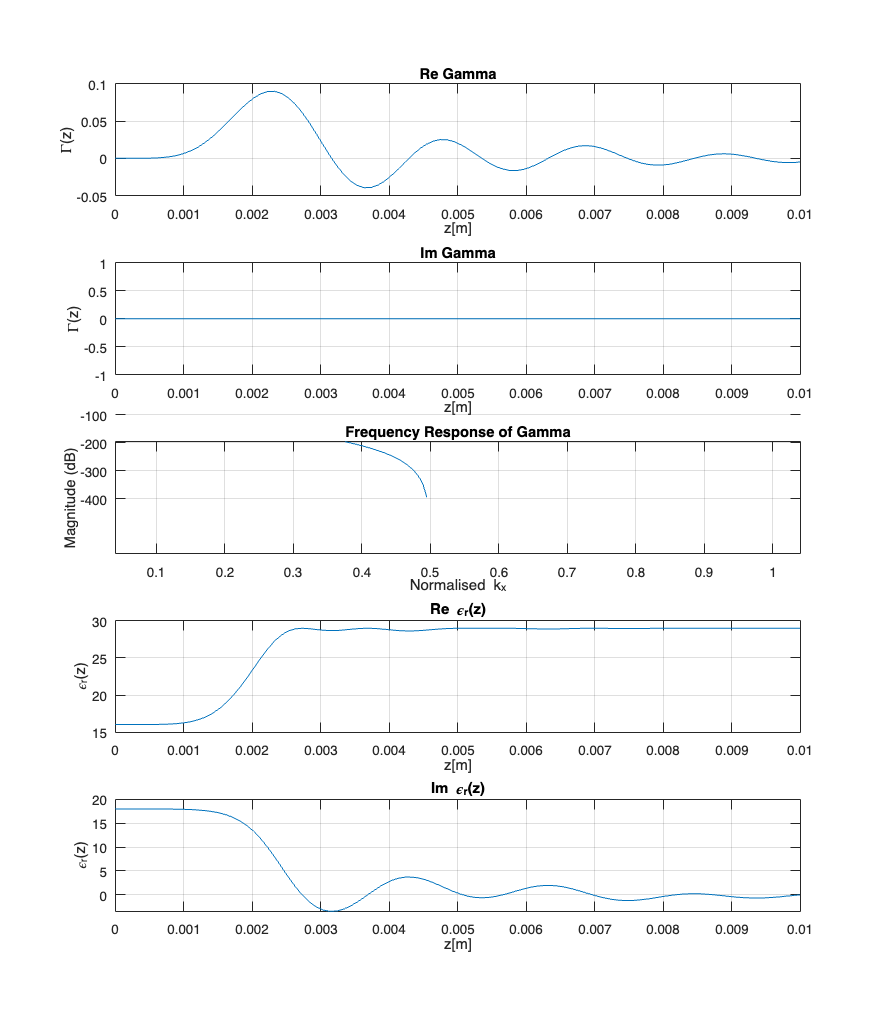


figure1=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(z, real(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Re Gamma")

subplot(5,1,2)
plot(z, imag(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Im Gamma")

subplot(5,1,3)
plot(w/(2*pi), 20*log10(abs(Hz)));
xlabel('Normalised k_x');
ylabel('Magnitude (dB)');
grid("on")
title('Frequency Response of Gamma');

subplot(5,1,4)
plot(z, real(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Re \epsilon_r(z)")

subplot(5,1,5)
plot(z, imag(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Im \epsilon_r(z)")

Temporal change

clear Gamma dGamma
T = 1e-9;
N_T = 100;
t = linspace(0, T, N_T);

% we use a chebyshev's Low Pass Filter

fc = omega/1e2; % cutoff frequency
fs = omega; % sampling freq
rp = 1; % ripple

% Calculate analog cutoff frequency and convert to digital
wc = 2*pi*fc; % analog cutoff frequency
wd = 2*pi*fc/fs; % digital cutoff frequency

% Design Chebyshev Type I filter coefficients
[n, Wn] = cheb1ord(wd, 0.5*wd, rp, 60);
[bc, ac] = cheby1(n, rp, Wn);

% take delta function as input so that output will give Gamma(t)
x = [1, zeros(1, N_L-1)];

Gamma = filter(bc, ac, x); % Gamma(z)
[Ht, w] = freqz(bc, ac, N_T); % freq resp

dGamma = gradient(Gamma); % Gamma'(z)


a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(T/N_T) - cumtrapz(a(1))*(T/N_T);

% Calculate I(z)
I = exp(int_a);

D = cumtrapz(I.*b)*(T/N_T) - cumtrapz(I(1)*b(1))*(T/N_T);
epst = ( I(1)*(1/(5*sqrt(eps_0)))*I.^(-1) - I.^(-1).*D ).^(-2);

disp(epst)

   1.0e-09 *

   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.0000i   0.2214 + 0.000

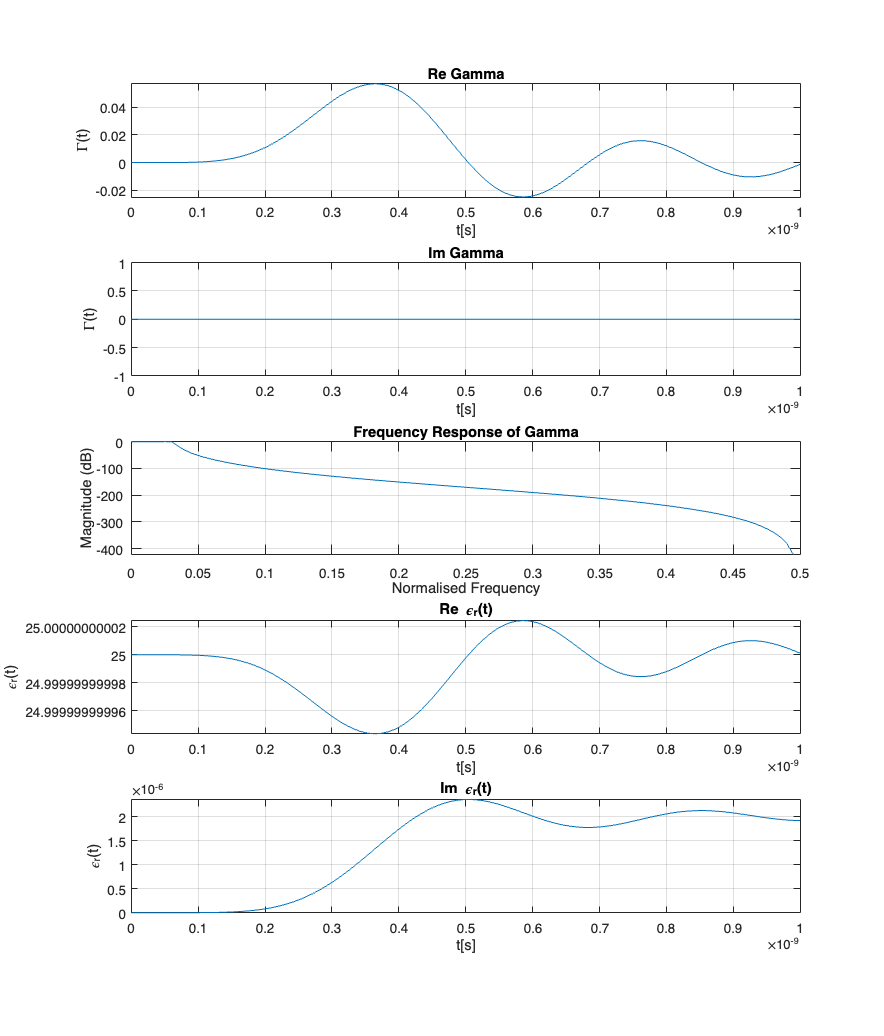


figure2=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(t, real(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Re Gamma")

subplot(5,1,2)
plot(t, imag(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Im Gamma")

subplot(5,1,3)
plot(w/(2*pi), 20*log10(abs(Ht)));
xlabel('Normalised Frequency');
ylabel('Magnitude (dB)');
grid("on")
title('Frequency Response of Gamma');

subplot(5,1,4)
plot(t, abs(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("Re \epsilon_r(t)")

subplot(5,1,5)
plot(t, imag(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("Im \epsilon_r(t)")

### Relating with $L$ and $C$

Spatial

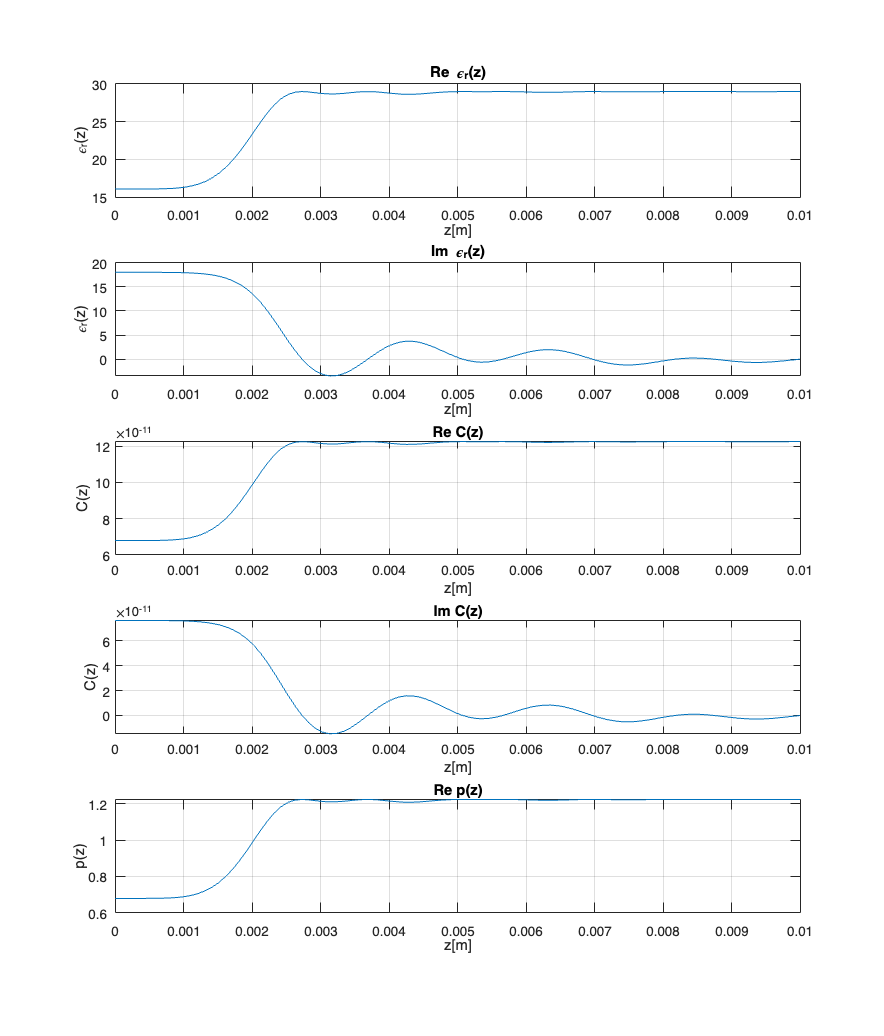

% Random values for L and C

L0 = 600e-9;

C = L0.*epsz./mu_0;

C0 = 20e-15;
Cshunt = 1e-10;

p = (C-C0)./Cshunt;

figure3=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(z, real(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Re \epsilon_r(z)")

subplot(5,1,2)
plot(z, imag(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Im \epsilon_r(z)")

subplot(5,1,3)
plot(z, real(C));
grid("on")
xlabel("z[m]")
ylabel("C(z)")
title("Re C(z)")

subplot(5,1,4)
plot(z, imag(C));
grid("on")
xlabel("z[m]")
ylabel("C(z)")
title("Im C(z)")

subplot(5,1,5)
plot(z, real(p));
grid("on")
xlabel("z[m]")
ylabel("p(z)")
title("Re p(z)")

Temporal

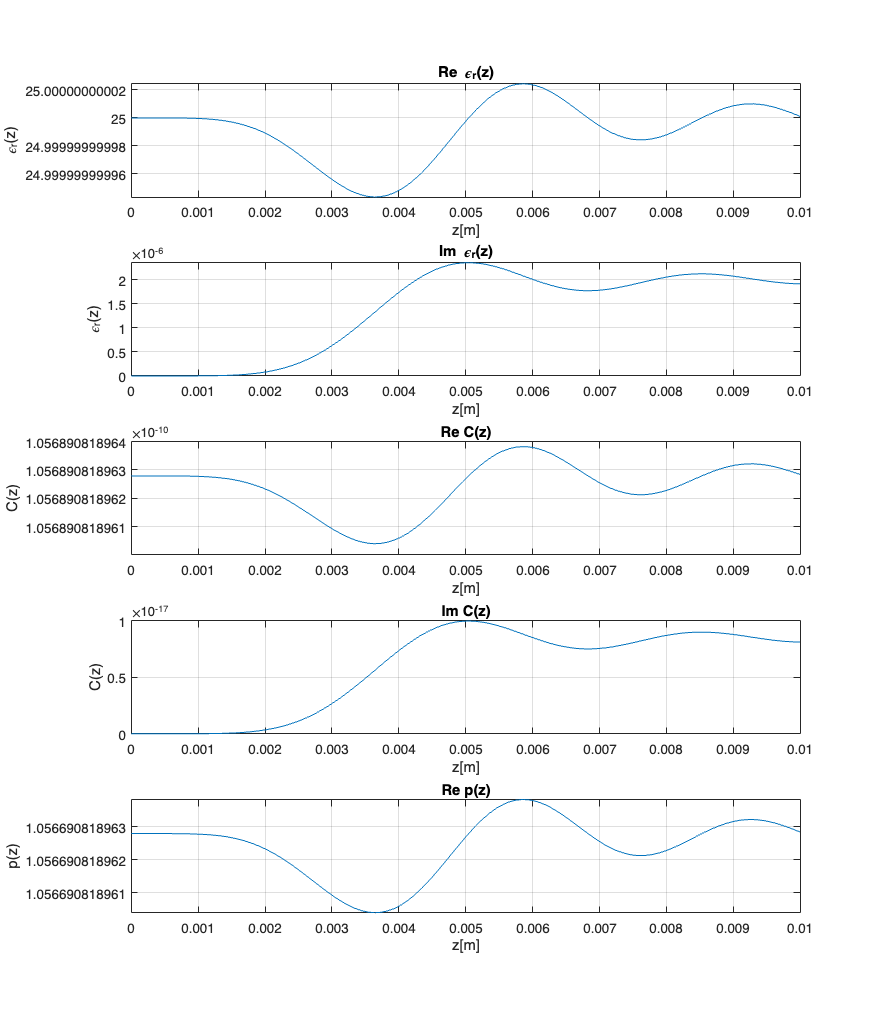

% Random values for L and C

L0 = 600e-9;

C = L0.*epst./mu_0;

C0 = 20e-15;
Cshunt = 1e-10;

p = (C-C0)./Cshunt;

figure3=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(z, real(epst/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Re \epsilon_r(z)")

subplot(5,1,2)
plot(z, imag(epst/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Im \epsilon_r(z)")

subplot(5,1,3)
plot(z, real(C));
grid("on")
xlabel("z[m]")
ylabel("C(z)")
title("Re C(z)")

subplot(5,1,4)
plot(z, imag(C));
grid("on")
xlabel("z[m]")
ylabel("C(z)")
title("Im C(z)")

subplot(5,1,5)
plot(z, real(p));
grid("on")
xlabel("z[m]")
ylabel("p(z)")
title("Re p(z)")